# Data Complexity in Networks and the Brain

© Moo K. Chung University of Wisconsin

November 26, 2010

This lecture introduces several related notions of geometric complexity:

1. Self-similar fractals such as the Hilbert curve

2. Intrinsic dimension of point-cloud data

3. Correlation dimension based on pairwise distances

4. Box-counting dimension

5. Application of box counting to brain networks - understanding the limitation of box counting method

6. Comparison with random graphs

A central idea is that the dimension of a dataset need not equal the dimension of the ambient space in which the data are represented. If a dataset is embedded in $\mathbb{R}^{D_e}$ but occupies a structure with intrinsic dimension $D_i$, then $D_i \leq D_e$. Fractal dimension provides one way of quantifying this intrinsic geometric complexity. Different definitions of fractal dimension measure scaling in different ways.

## Hilbert Curve: A Classical Space-Filling Fractal

The Hilbert curve illustrates how a geometrically simple one-dimensional path can progressively fill a two-dimensional region. At every iteration, the previous curve is replaced by four transformed copies of itself. As the number of iterations increases, the limiting Hilbert curve is space filling. Its topological dimension is 1 because it is a curve, while its limiting space-filling fractal dimension is 2.

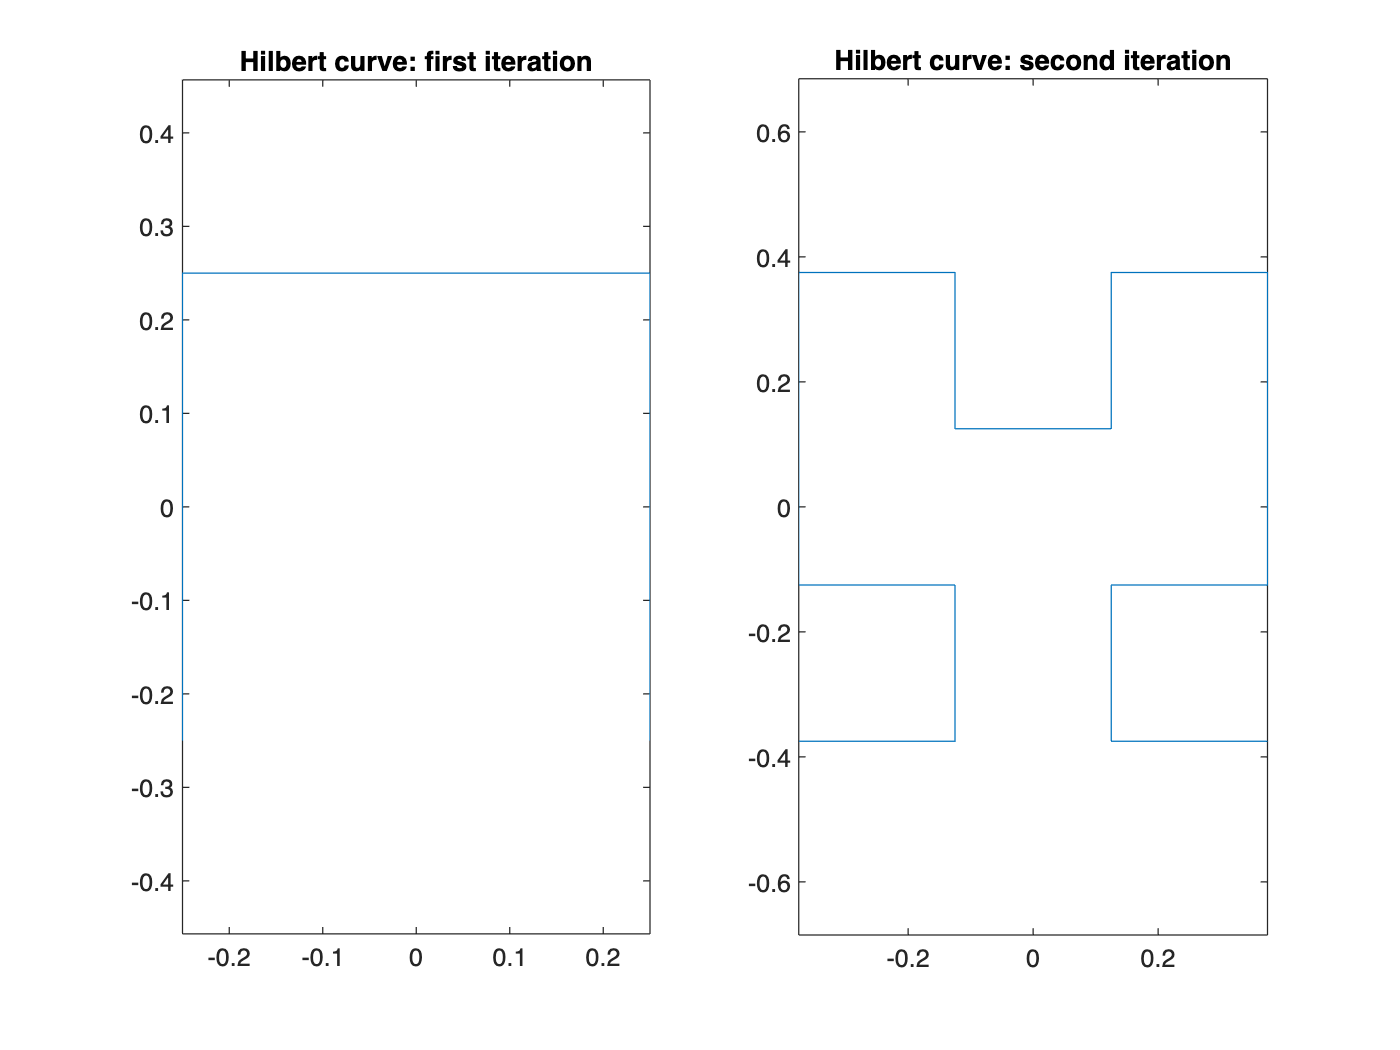


x=0; 
y=0;

newx=.5*[-.5+y -.5+x .5+x .5-y];
newy=.5*[-.5+x .5+y .5+y -.5-x];

figure; subplot(1,2,1)
plot(newx,newy,'-')
axis equal
title('Hilbert curve: first iteration')

x=newx;
y=newy;

newx=.5*[-.5+y -.5+x .5+x .5-y];
newy=.5*[-.5+x .5+y .5+y -.5-x];

subplot(1,2,2)
plot(newx,newy,'-')
axis equal
title('Hilbert curve: second iteration')

The recursive construction can be continued to an arbitrary level $n$. As $n$ increases, the curve becomes increasingly dense in the plane. In the limit, the Hilbert curve has fractal dimension $D=2$. This example demonstrates that dimension can describe how densely an object occupies space rather than simply the number of coordinates used to represent it.

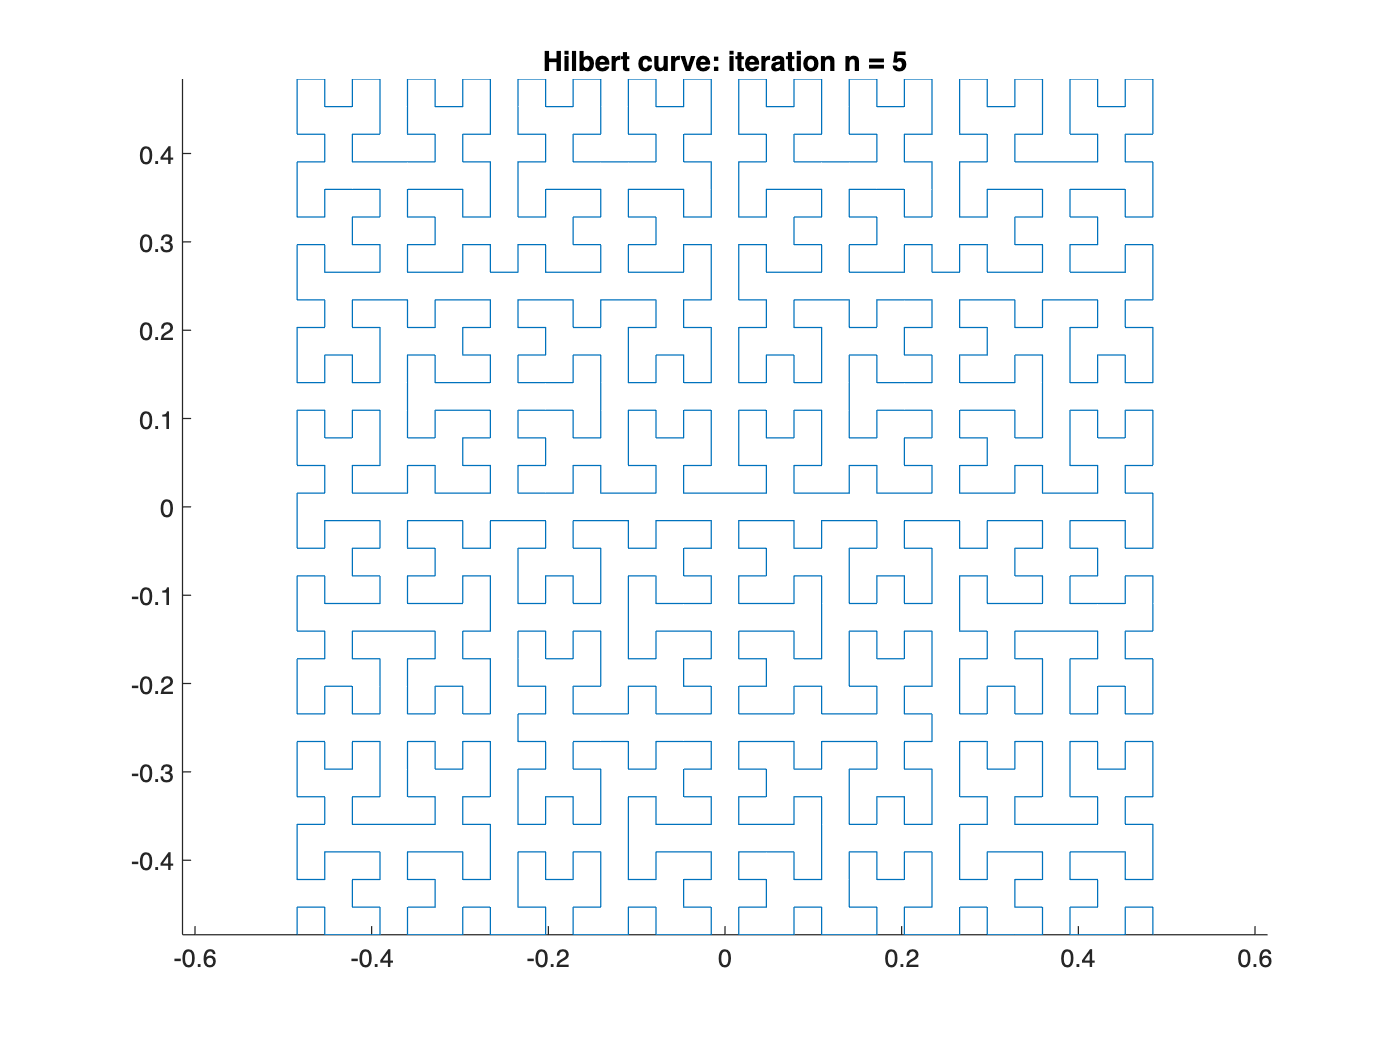


n=5;
[x,y]=hilbertcurve(n);

figure;
line(x,y)
axis equal
title(['Hilbert curve: iteration n = ' num2str(n)])

## Fractal Dimension of Point-Cloud Data

Consider observations $x_1,\ldots,x_N \in \mathbb{R}^{D_e}$. Although the embedding dimension is $D_e$, the observations may lie near a lower-dimensional geometric structure. For example, points lying near a line in $\mathbb{R}^2$ have $D_e=2$, but $D_i\approx 1$. Points filling an area in $\mathbb{R}^2$ instead have $D_e=2$ and $D_i\approx 2$.

#### Example 1: Approximately One-Dimensional Point Cloud

The points follow approximately the line $y=x$ with additive noise. Therefore, the data are embedded in two dimensions but are concentrated around a one-dimensional structure.

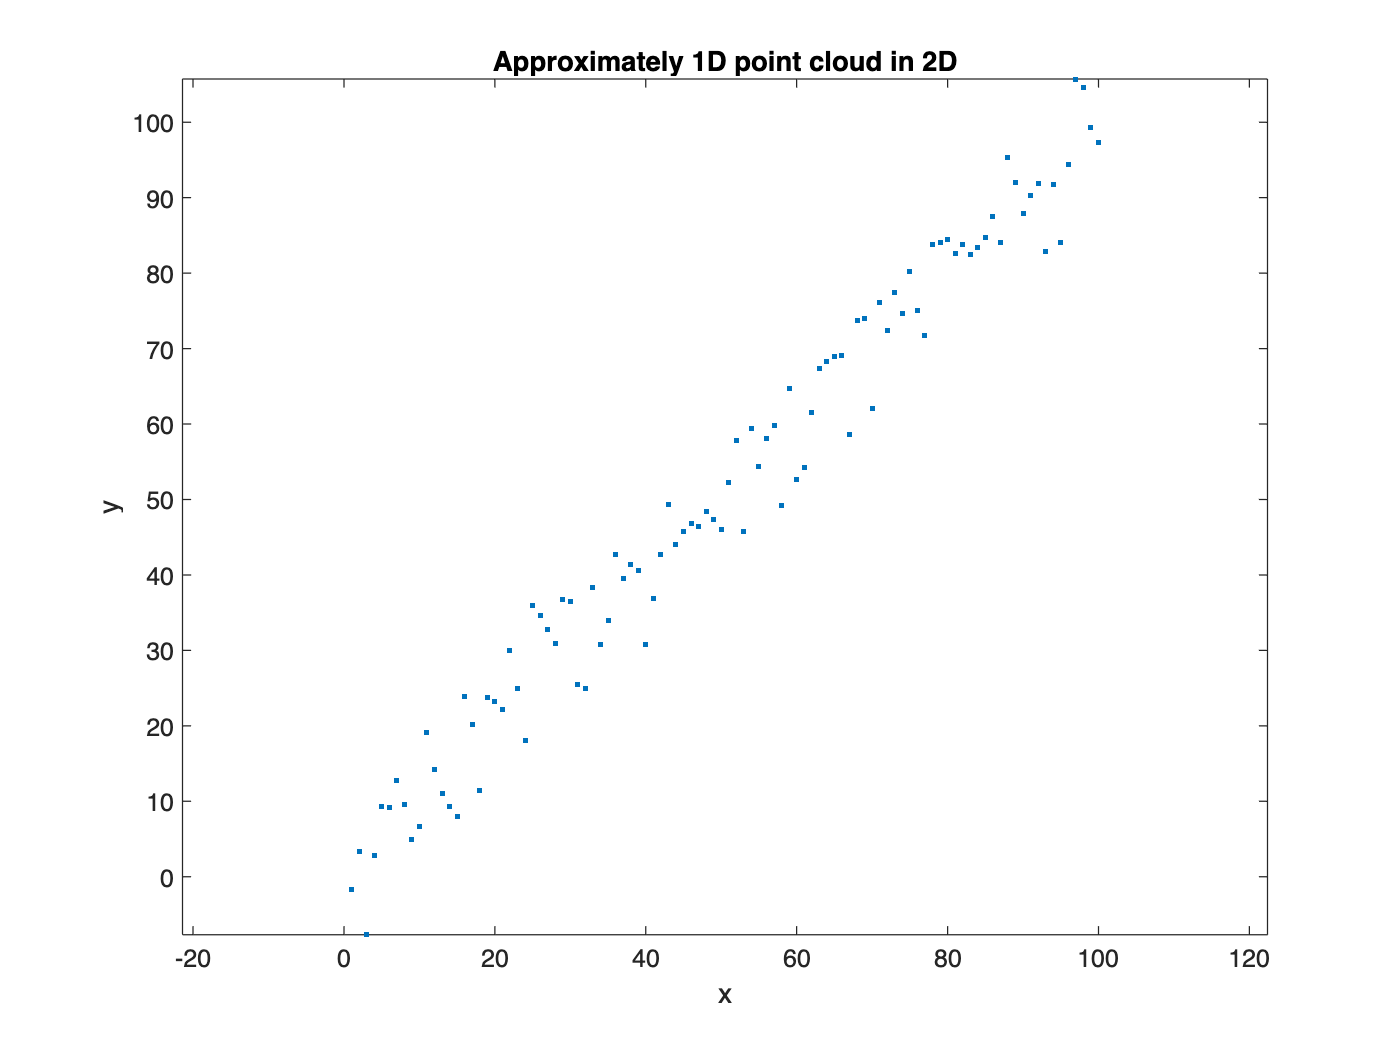


x=1:100;
y=x + normrnd(0,5,1,100);

figure;
plot(x,y,'.')
axis equal
xlabel('x')
ylabel('y')
title('Approximately 1D point cloud in 2D')

#### Example 2: Two-Dimensional Point Cloud

Increasing the noise spreads the observations more broadly through the plane. The point cloud therefore behaves more like a two-dimensional object over an appropriate range of spatial scales.

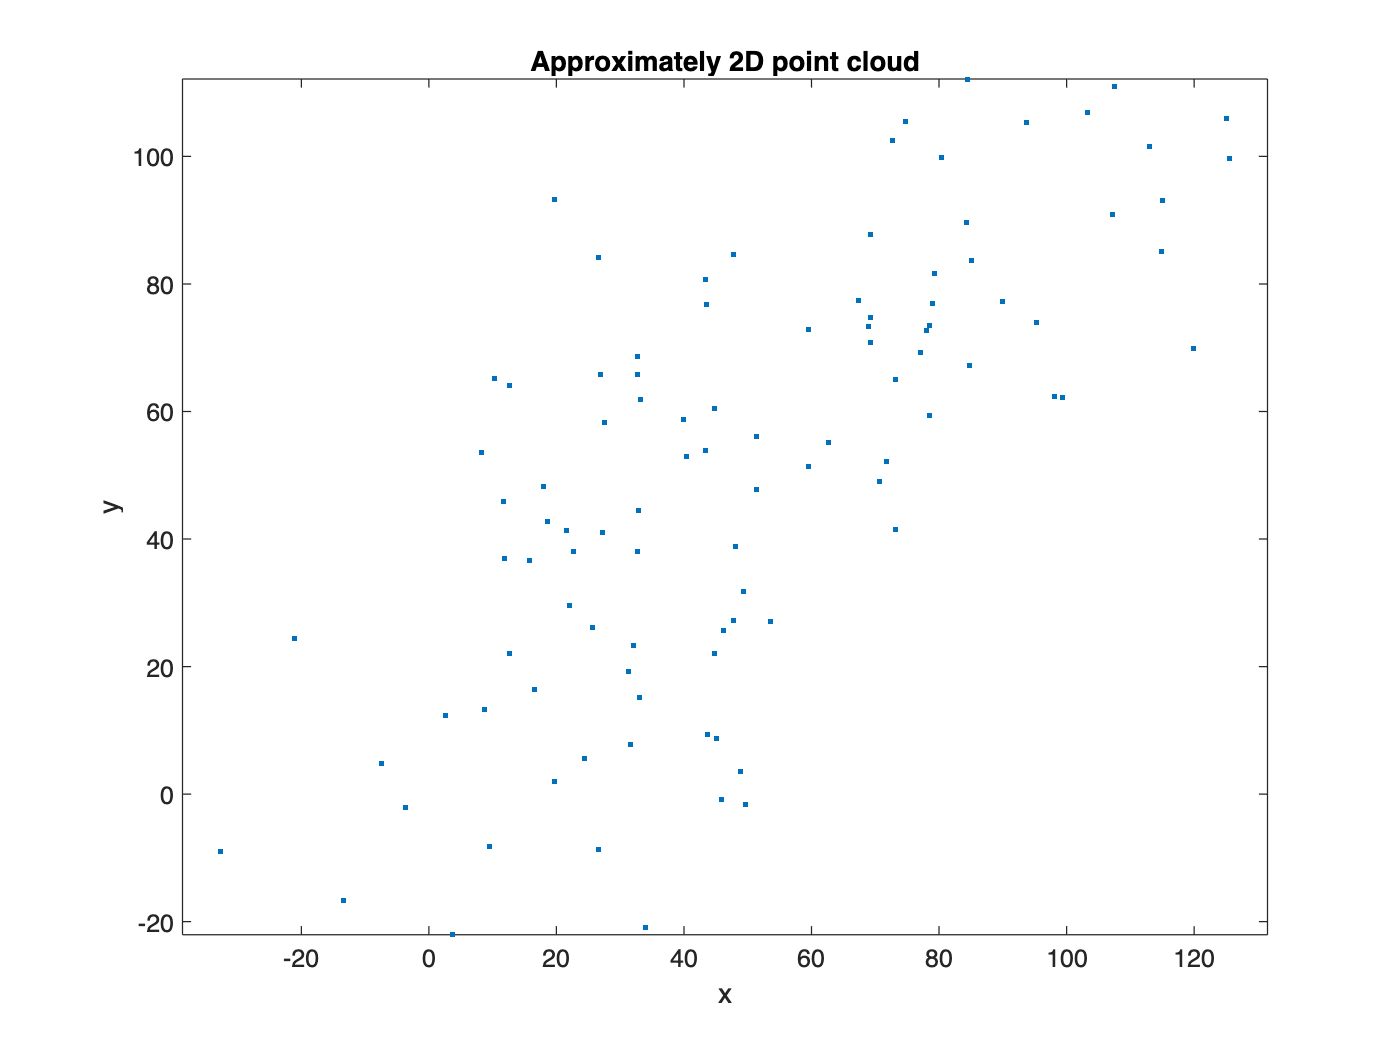

a=1:100;
x=a + normrnd(0,20,1,100);
y=a + normrnd(0,20,1,100);

figure;
plot(x,y,'.')
axis equal
xlabel('x')
ylabel('y')
title('Approximately 2D point cloud')

## Correlation Dimension

Correlation dimension is based on the distances between all pairs of observations. For observations $x_i=(x_i,y_i)$ and $x_j=(x_j,y_j)$, the Euclidean distance is

$d_{ij}=\sqrt{(x_i-x_j)^2+(y_i-y_j)^2}$. The matrix $D$ contains these pairwise distances.

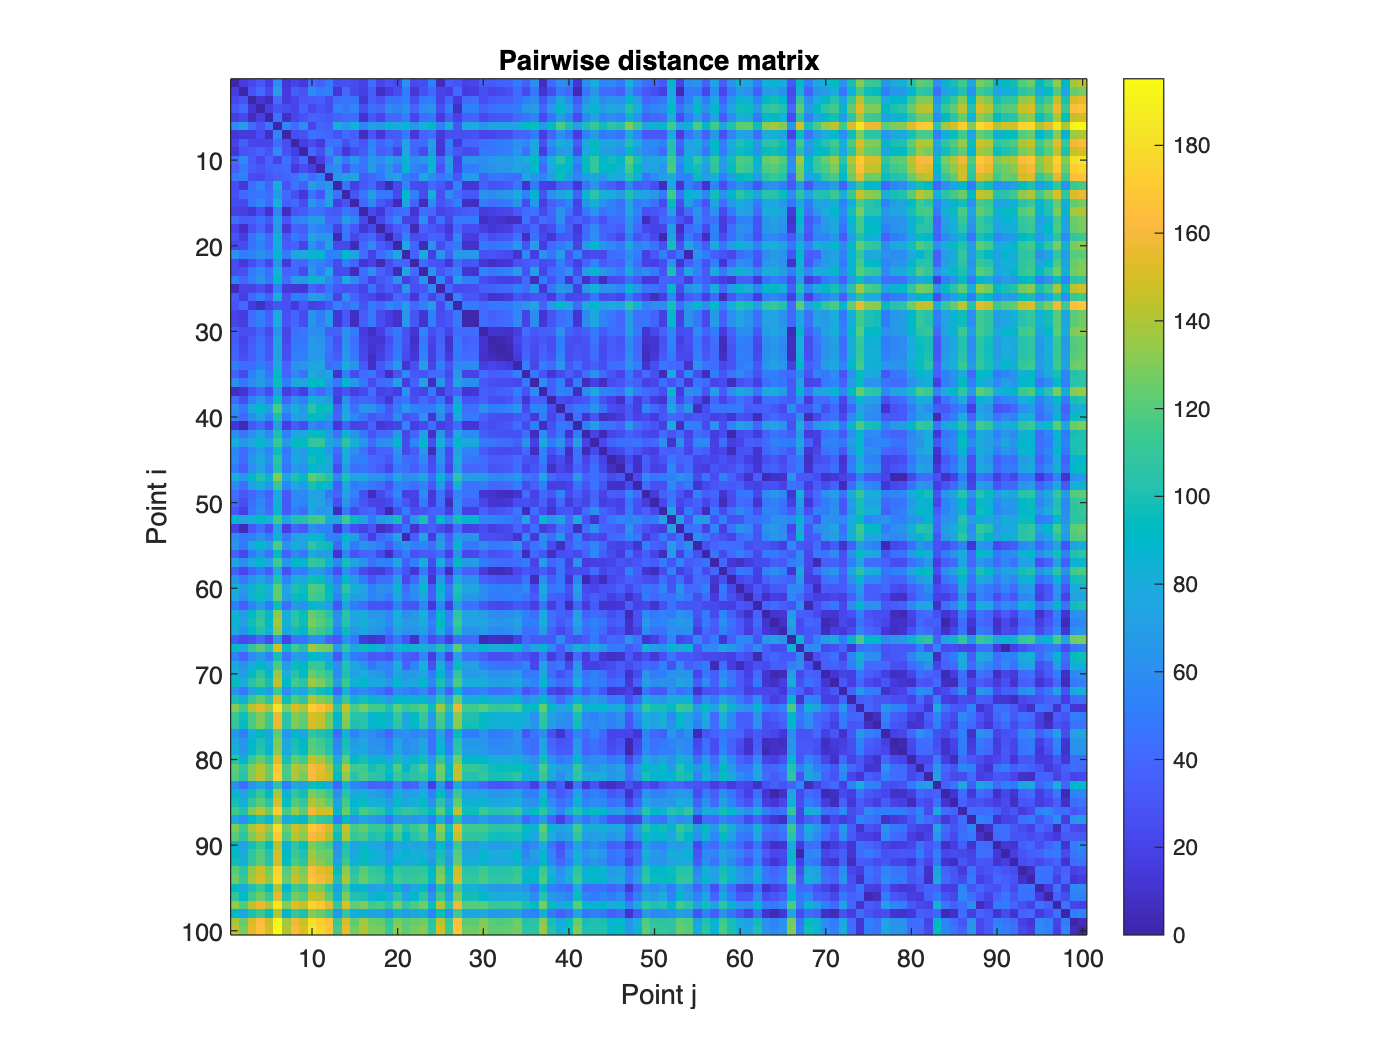


D=zeros(100,100);

for i=1:100
    D(i,:)=sqrt((x-kron(ones(1,100),x(i))).^2 + ...
                (y-kron(ones(1,100),y(i))).^2);
end

figure;
imagesc(D)
axis image
colorbar
xlabel('Point j')
ylabel('Point i')
title('Pairwise distance matrix')

The correlation dimension measures how rapidly the number of nearby pairs increases as the distance threshold $k$ increases. Define the correlation integral

$C(k)=\frac{2}{N(N-1)}\sum_{i<j}I(d_{ij}<k)$,

where $I(\cdot)$ is the indicator function. If the point cloud exhibits scale-invariant geometry over some range of $k$, then $C(k)\propto k^{D_c}$, where $D_c$ is the correlation dimension. Taking logarithms gives $\log C(k)=D_c\log k+\mathrm{constant}$. Therefore, the correlation dimension is estimated as the slope of the approximately linear portion of the log-log plot:

$D_c\approx \frac{\Delta\log C(k)}{\Delta\log k}$.

*Note*: A finite empirical dataset will generally not follow a power law over every possible scale. At very small scales, discreteness and noise dominate. At very large scales, the count saturates because nearly all pairs are included. The dimension should therefore be interpreted over the scale range in which approximately linear log-log scaling occurs.

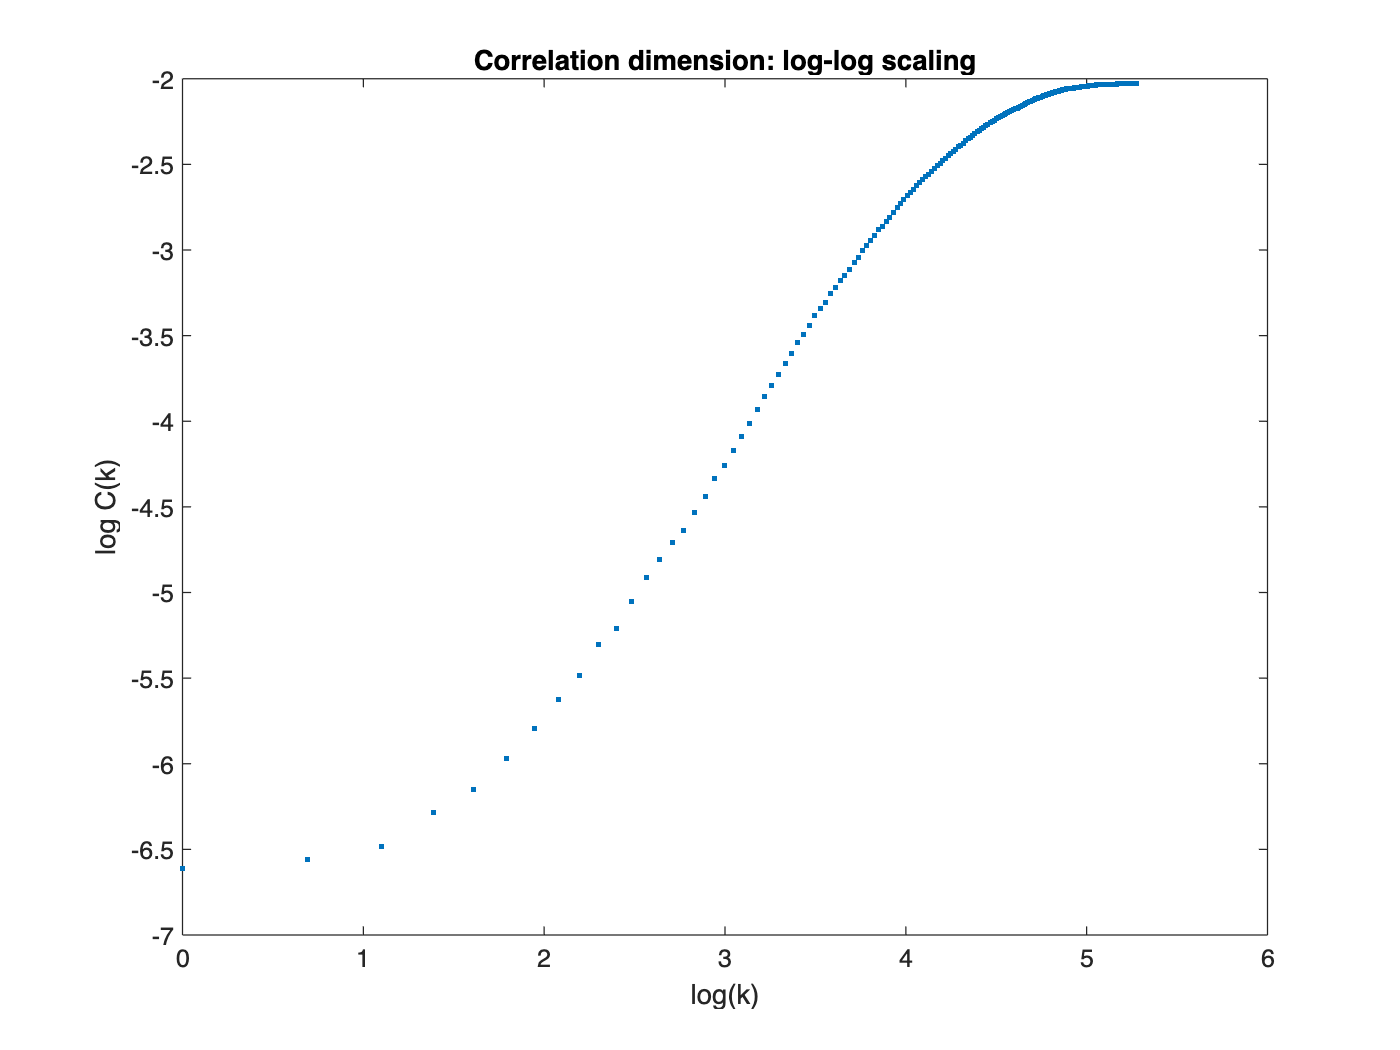

maxk=floor(max(max(D)));
D=reshape(D,100^2,1);

count=[];

for k=1:maxk
    count(k)=length(find(D<k))/2;
end

count=count/maxk^2;

figure;
plot(log(1:maxk),log(count),'.')
xlabel('log(k)')
ylabel('log C(k)')
title('Correlation dimension: log-log scaling')


b=regress(log(count)',[ones(maxk,1) log(1:maxk)']);

%The fitted model is log C(k) = b(1) + b(2) log(k). Thus b(2) estimates the correlation dimension over the fitted range.

correlation_dimension=b(2)

correlation_dimension = 1.0724

#### Interpretation of Correlation Dimension

Correlation dimension can be understood as a neighbor-growth dimension. Around a point $x$, consider a ball of radius $k$. If the data occupy a $D_c$-dimensional structure, the number of neighboring pairs grows approximately as $C(k)\propto k^{D_c}$. 

For a line: $C(k)\propto k^1$. 

For a plane: $C(k)\propto k^2$.

For a three-dimensional volume: $C(k)\propto k^3$.

A non-integer value such as $D_c=1.6$ indicates geometric scaling intermediate between an ideal one-dimensional curve and a two-dimensional region.

## Box-Counting Method

Box counting provides another definition of fractal dimension. Cover an object with boxes of side length $\epsilon$. Let $N(\epsilon)$ denote the number of boxes containing at least part of the object. For a fractal or approximately scale-invariant object,

$N(\epsilon)\propto\epsilon^{-D_B}$,

where $D_B$ is the box-counting dimension. Taking logarithms gives

$\log N(\epsilon)=-D_B\log(\epsilon)+\mathrm{constant}$.

Hence $D_B=-\frac{\Delta\log N(\epsilon)}{\Delta\log\epsilon}$.

Correlation dimension and box-counting dimension are therefore closely related scaling dimensions, but they count different objects:

Correlation dimension counts nearby PAIRS OF POINTS. Box-counting dimension counts OCCUPIED BOXES.

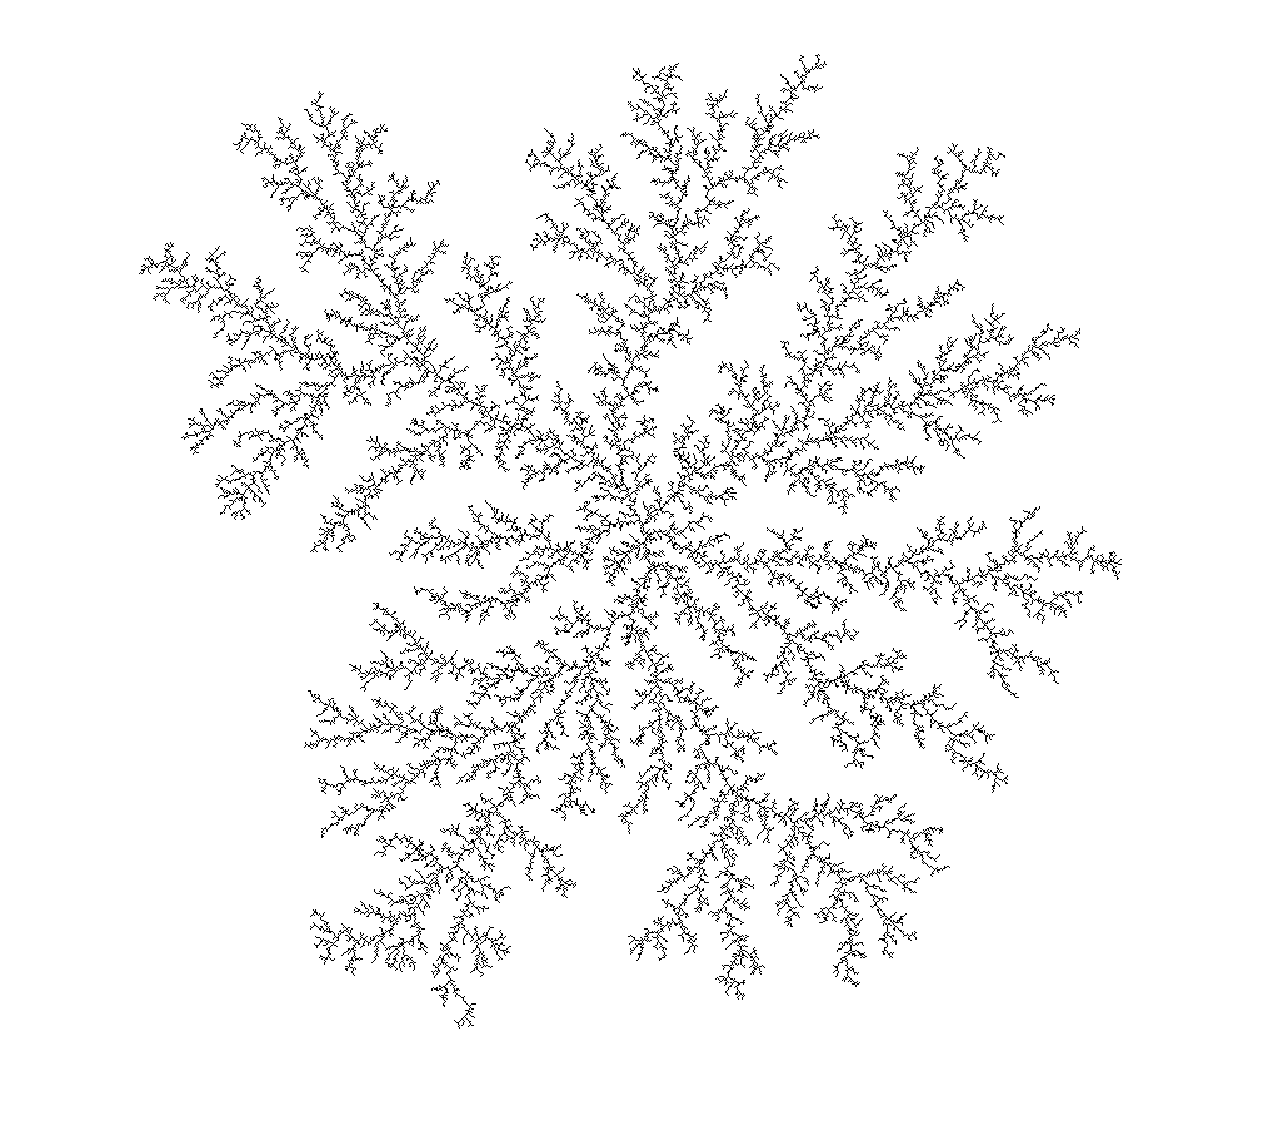

[C,map]=imread('fractal.gif');
figure;
imshow(C,map)

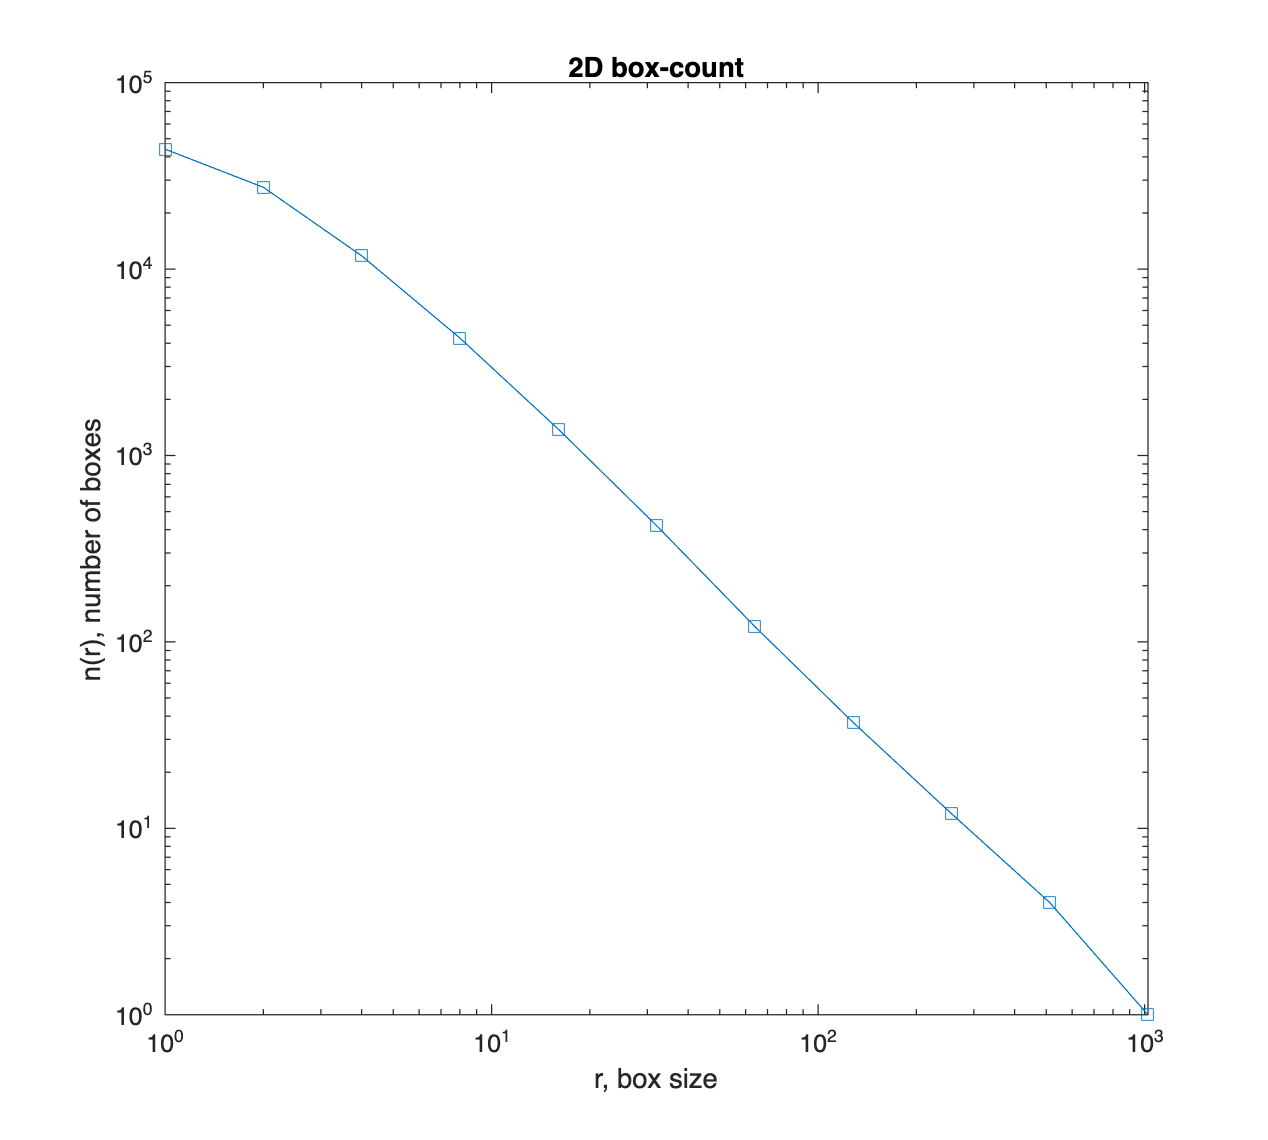

[N,R]=boxcount(C,'plot');

## Box Counting Applied to a Brain Fiber Network

We now apply the same general scaling idea to structural brain connectivity. This is to illustrate the inusfficiency of box counting method to non-Euclidean data.

load SL.mat
% SL contains reconstructed white-matter streamlines. Each streamline is
% represented by a sequence of three-dimensional coordinates.

%% Visualize the Fiber Bundle
% To avoid displaying all streamlines simultaneously, one tract out of
% every 30 is displayed.

figure; subplot(1,3,1)

for i=1:100:10000
    tract=SL{i}';

    if size(tract,2)>10
        hold on
        plot3(tract(1,:),tract(2,:),tract(3,:),'b')
    end
end

axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('White-matter fiber trajectories')

%% Obtain Fiber Endpoints
% Each tract has two endpoints. These endpoints can be used to construct
% an approximate network representation of the fiber system.

endp=get_endp_tracts(SL,10);

hold on
plot3(endp(:,1,1),endp(:,1,2),endp(:,1,3),'.r')
hold on
plot3(endp(:,2,1),endp(:,2,2),endp(:,2,3),'.r')


#### Epsilon-Neighborhood Graph Construction

The tract system is converted into a graph by connecting sufficiently nearby or related fiber endpoints. The resulting adjacency matrix adj represents the connectivity pattern of the reconstructed network. The method is published in 

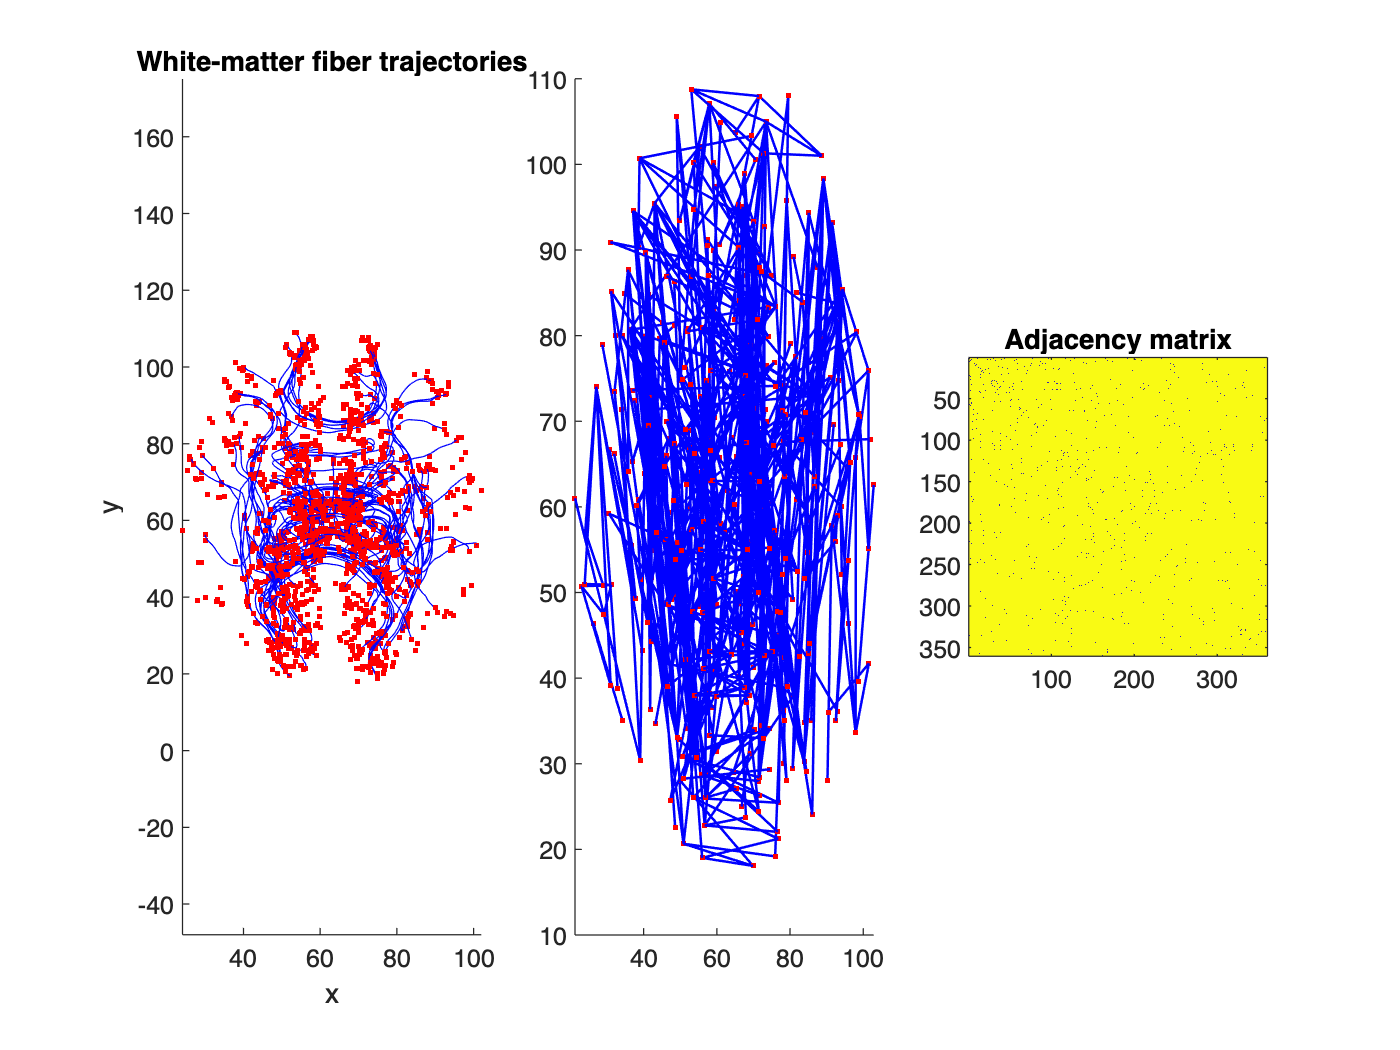

[adj,prob,vertices]=tract2graph(SL,6);

subplot(1,3,2); figure_dtigraph(adj,vertices); 

subplot(1,3,3); 
imagesc(-adj); axis square
title('Adjacency matrix')

#### Box Counting of the Adjacency Matrix

Here box counting is applied directly to the binary pattern of the adjacency matrix. This should be interpreted as the box-counting dimension of the adjacency-matrix pattern, not automatically as the geometric fractal dimension of the underlying anatomical network. If $N(R)\propto R^{-D_B}$, then $\log N(R)=a-D_B\log R$. Therefore the estimated box-counting dimension is $D_B=-b_2$.

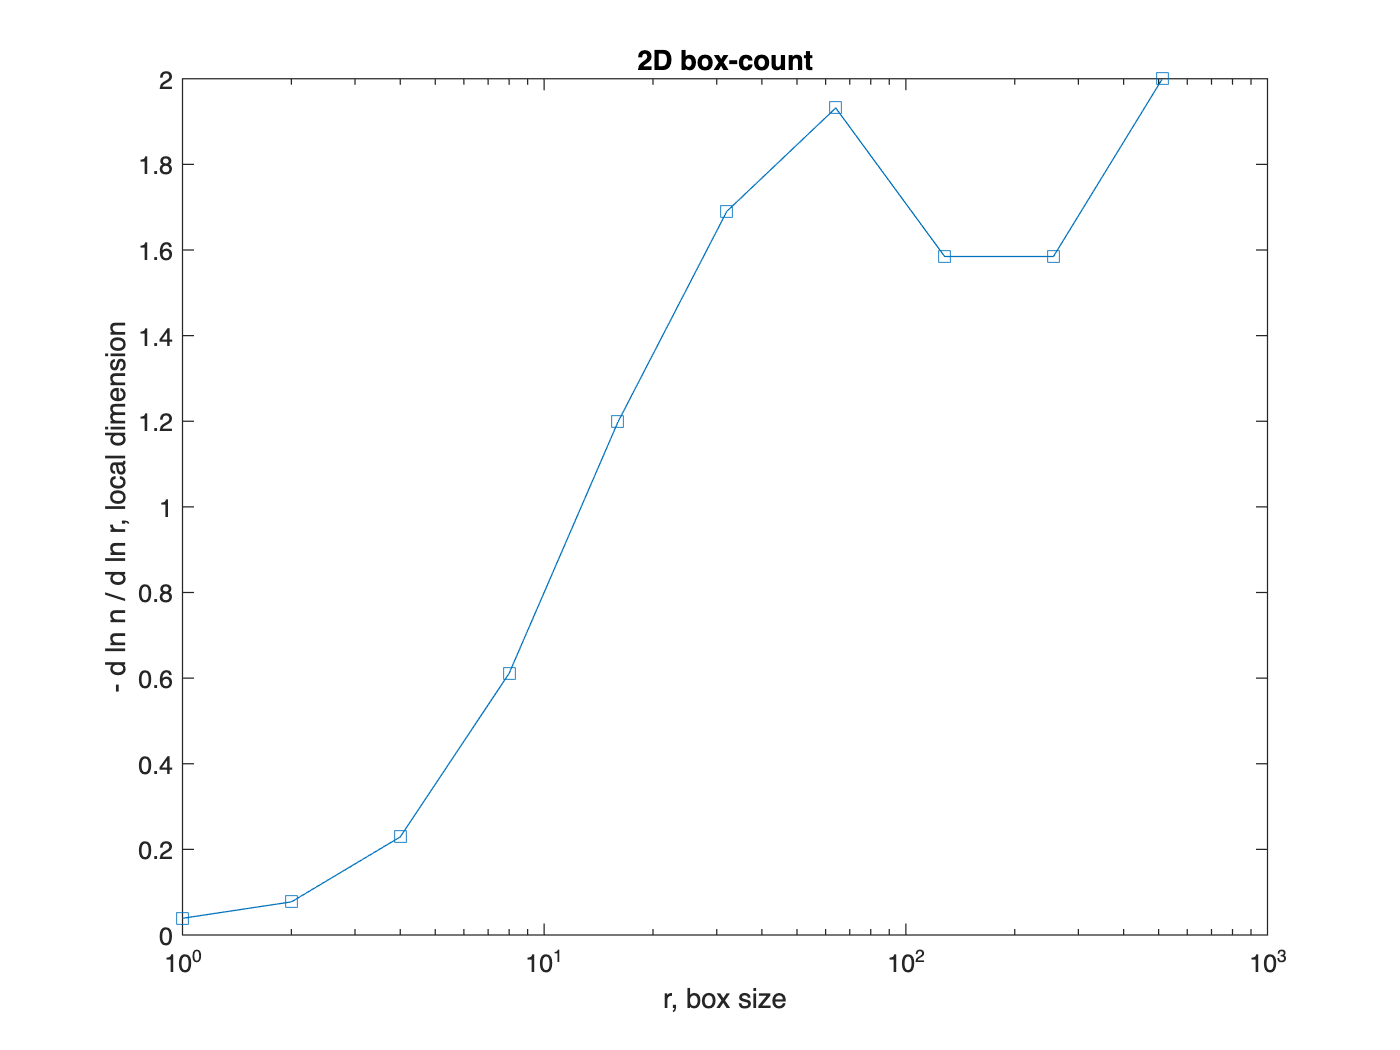

figure;
[N,R]=boxcount(adj,'slope');


k=length(N);
b=regress(log(N)',[ones(k,1) log(R)']);
FD=-b(2)

FD = 1.1629

For an undirected graph, the adjacency matrix is symmetric. Thus the upper and lower triangular portions contain duplicated information. We retain the upper triangular part to examine how this duplication influences the estimated box-counting dimension.

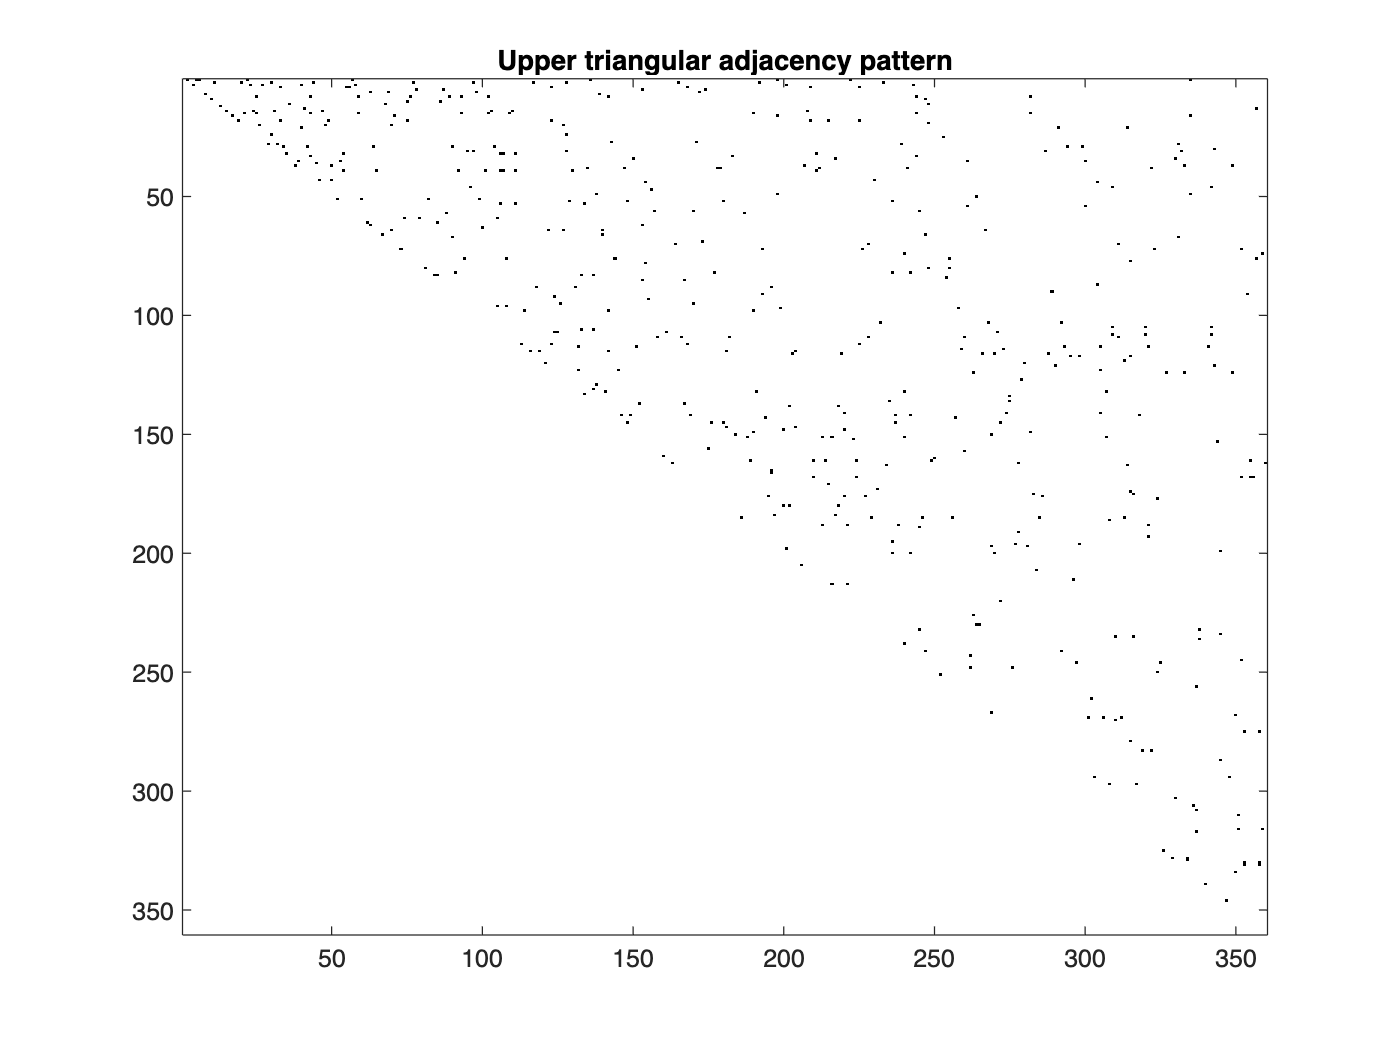

n=size(adj,1);
T=zeros(n,n);

for i=1:n
    T(i,i:end)=adj(i,i:end);
end

figure;
imagesc(-T)
colormap('bone')
title('Upper triangular adjacency pattern')

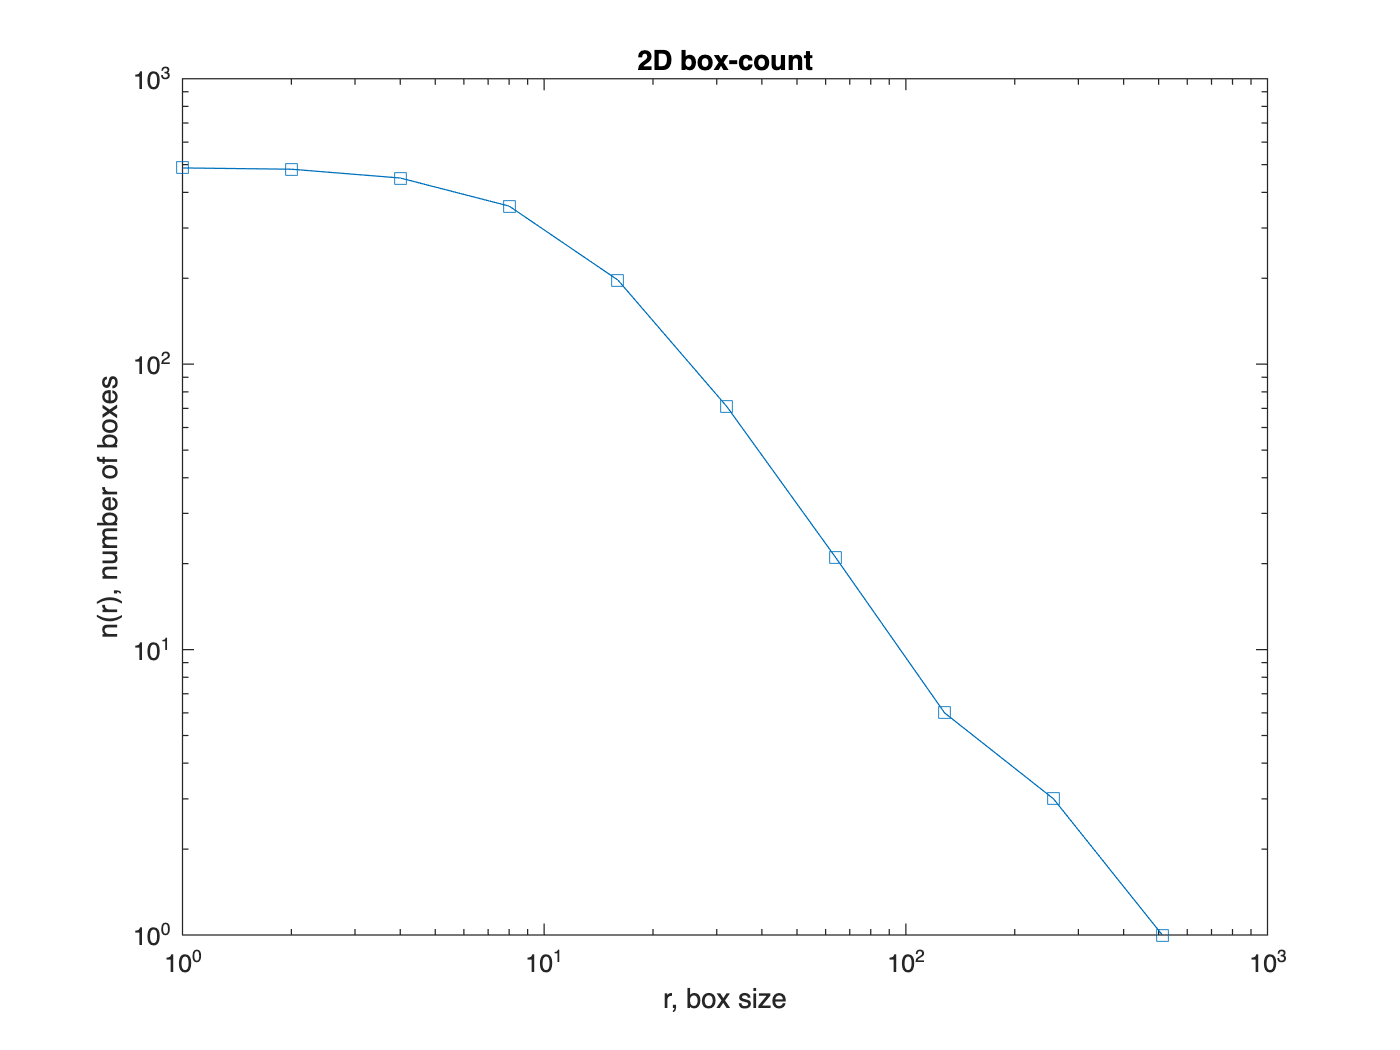


figure;
[N,R]=boxcount(T,'plot');


k=length(N);
b=regress(log(N)',[ones(k,1) log(R)']);
FD=-b(2)

FD = 1.0698

**Problem: **Develop a dimension estimation technique for network and graph data. This can be done through diffusion dimension computed through heat diffusion on manifolds.  